load('rawop/mat_pos.mat')
% load('positionmatrix.mat','walls')
x=finalmat(10000,1);y=finalmat(10000,2);
pts=linspace(100,700,400)

pts =   100.0000  101.5038  103.0075  104.5113  106.0150  107.5188  109.0226  110.5263  112.0301  113.5338  115.0376  116.5414  118.0451  119.5489  121.0526  122.5564  124.0602  125.5639  127.0677  128.5714  130.0752  131.5789  133.0827  134.5865  136.0902  137.5940  139.0977  140.6015  142.1053  143.6090  145.1128  146.6165  148.1203  149.6241  151.1278  152.6316  154.1353  155.6391  157.1429  158.6466  160.1504  161.6541  163.1579  164.6617  166.1654  167.6692  169.1729  170.6767  172.1805  173.6842


points=[x,y];
N=histcounts2(y(:),x(:),pts,pts);
% heatmap(points)
% Plot scattered data (for comparison):
% subplot(1, 2, 1);
% scatter(x, y, 'r.');
% axis equal;
% set(gca, 'XLim', pts([1 end]), 'YLim', pts([1 end]));

% Plot heatmap:
% subplot(1, 2, 2);
% imagesc(pts, pts, N);
% axis equal;
% set(gca, 'XLim', pts([1 end]), 'YLim', pts([1 end]), 'YDir', 'normal');
% plot(0,0)
% hold on
% line(walls(r,[3,4]),walls(r,[1,2]))


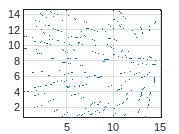


% hold off

load('rawop/mat_pos.mat')
NoOfBins = 1000; %or whatever you want
X=mat_pos(1:1000,1);Y=mat_pos(1:1000,2);
[gridprob, xedges, yedges] = histcounts2(X, Y, NoOfBins, 'Normalization', 'probability');
% surf(mean(xedges([1:end-1;2:end])), mean(yedges([1:end-1;2:end])), gridprob)
% contourf(X,Y,gridprob)
h = histogram2(X,Y, 'NumBins', 200);
% contour(X,Y,h)
shading interp

% shading("interp")
%or use
%histogram2(X, Y, NoOfBins, 'Normalization', 'probability')

clear all

load('rawop/mat_pos.mat')
% D1 = load('X.mat');
% D2 = load('Y.mat');
% X = D1.X;
% Y = D2.Y;
n=1000

n = 1000

hh3=zeros([60,60]);
for i=1:n
data = [mat_pos(100*i+(1:100),1),mat_pos(100*i+(1:100),2)];
hh3 = hh3+hist3(data, 'Nbins',[1 1]*60);
end

Index
in
position
1
exceeds
array
bounds.
Index
must
not
exceed
16300.

figure
image(flipud(hh3))
ax = gca;
xt = ax.XTick;
yt = ax.YTick;
ax.XTickLabel = xt*10;
set(ax, 'YTick',[0 yt], 'YTickLabel', [flip([0 yt])]*10)
